# Cálculo de bifurcación de sistema dinámico con Paralelización de núcleos. 

# Dynamical system bifurcation analysis with core parallelization.

## Paralellization

Se calcula el diagrama de bifurcación del sistema de Rössler, a partir de la variación de su párametro $b = \{0.05, \ldots, 2\}$. Se usan dos tipos de proceso iterativo, el primero es a partir de la paralelización del ciclo for mediante la instrucción *parfor*. No se hace el ajuste del número de núcleos de la computadora, ya que el algorítmo los calcula inmediatamente al correr la función *parfor*.

El segundo método, es a partir de un *for* simple. Esto para contrastar los tiempos de simulación, y si es posible realizar la división de actividades del procesamiento de las señales de tiempo continuo en los diferentes núcleos.

--------------------------------------------------------------------------------------------------------------------

The Rössler system's bifurcation diagram is calculated from the variation of its parameters a,b, or c. Generally, the values are set to: $b = \{0.05, \ldots, 2\}$.Two types of iterative processes are used. The first is from the parallelization of the for cycle using the parfor instruction. The number of computer cores is not adjusted since the algorithm calculates them immediately when the parfor function is run.

The second method is simple. This is to compare the simulation times and, if possible, divide the activities of processing continuous-time signals between the different cores.


% function RunDynamicalSystemsPAR
    %parpool(4)                             % Depende de núcleos del PC
    
    NumVectores = 200;                      % Cantidad de datos parametro
    b = (linspace(0.05,2,NumVectores))';    % Parametro de bifurcacion
    h = 0.01;                               % Tamaño de paso integracion
    ti = 0; tf = 2000;                      % Tiempo inicial y final
    t = (ti:h:tf)';                         % Estados de tiempo para iterar
    fhandle = @RosslerRK;                   % Sistema a estudiar
    CI = [1,0,1];                           % Vector de condiciones iniciales
    
    % Prealocacion de vectores de salida
    NumPuntosCruce = 500;                   % Estimacion de puntos de cruce
    BifurParameterB =  nan(NumPuntosCruce,NumVectores);   
    BifurStatesX    =  nan(NumPuntosCruce,NumVectores);
    
    SizeMax = nan(NumVectores,1);
    Transitorios = 150000;                   % Numero de estados a eliminar
    tic

    parfor indx = 1:NumVectores
        
        B = b(indx);                        % Seleccion del valor del parametro
        Salida = RungeKuttaPar(CI,h,fhandle,t,B);   % Integrador numerico
        X = Salida(Transitorios:end,1);     % Asignacion de estado X sin transitorios
        Y = Salida(Transitorios:end,2);     % Asignacion de estado Y sin transitorios
        Z = Salida(Transitorios:end,3);     % Asignacion de estado Z sin transitorios

        % Calculo de los índices que cruzan por el plano Y = 0
        diffY = diff(Y);                    % Calculo de la derivada de Y
        SignDiffY = sign(diff(Y));          % Vector de signos de derivada
        CruceCero = find((SignDiffY(1:end-1)-SignDiffY(2:end))==2); % 2-> Maximo local; -2 -> Minimo local
        VectorMaximos = [ones([length(CruceCero),1])*B X(CruceCero)]; % Determina los indices de X
        
        % Como los indices no tienen el mismo size por parametro, se hace
        % un vector preallocated con NaN para llenarse con datos
        VectorDummy = zeros(NumPuntosCruce,2); 
        VectorDummy(1:length(VectorMaximos),:) = VectorMaximos;
        BifurParameterB(:,indx) = VectorDummy(:,1);
        BifurStatesX(:,indx) = VectorDummy(:,2);
        SizeMax(indx) = length(VectorMaximos);
    end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 16 workers.


    tiempo2 = toc

tiempo2 = 11.3883

    max(SizeMax)

ans = 91

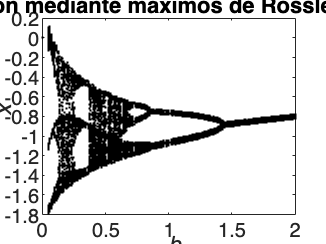


    figure
    plot(BifurParameterB,BifurStatesX,'.k','MarkerSize',0.1)
    title('Bifurcación mediante máximos de Rössler (Parallel)')
    xlabel('\it b')
    ylabel('\it x')

%end


## No Paralelization

Longitud = 200;
b = linspace(0.05,2,Longitud);
h = 0.01;
ti = 0; tf = 2000;
t = ti:h:tf;

Parameters.h = h;
Parameters.t = t;
Parameters.fhandle = @RosslerRK;

Parameters.CI = [1,0,1];


Bifurcacion = nan(floor(length(t)/2),2*Longitud);

indice2 = 1;
SizeMax = [];
%Transitorios = 50000;
tic
for indice = 1:Longitud
    
    %[t,Salida] = ode45(@Lorenz, 0:0.01:100,x0);
    Parameters.b = b(indice);
    Salida = RungeKutta(Parameters);
    X = Salida(Transitorios:end,1);
    Y = Salida(Transitorios:end,2);
    Z = Salida(Transitorios:end,3);
    diffY = diff(Y);
    SignDiffY = sign(diff(Y));
    CruceCero = find((SignDiffY(1:end-1)-SignDiffY(2:end))==2);
    VectorMaximos = [ones([length(CruceCero),1])*b(indice) X(CruceCero)];
    Bifurcacion(1:length(VectorMaximos),indice2:indice2+1) = VectorMaximos;
    indice2 = indice2+2;
    SizeMax = [SizeMax length(VectorMaximos)];
end
tiempo1 = toc

tiempo1 = 25.8529

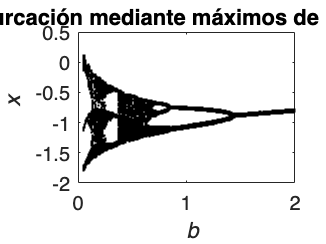


Bifurcacion = Bifurcacion(1:max(SizeMax),:);
BifurParameterB = Bifurcacion(:,1:2:length(Bifurcacion));
BifurStatesX = Bifurcacion(:,2:2:length(Bifurcacion));
figure
plot(BifurParameterB,BifurStatesX,'.k','MarkerSize',0.1)
title('Bifurcación mediante máximos de Rössler ')
    xlabel('\it b')
    ylabel('\it x')

## Sistemas Dinámicos

Se considera el sistema dinámico continuo de [Rössler](https://en.wikipedia.org/wiki/R%C3%B6ssler_attractor). 

--------------------------------------------------------------------------------------------------------------------

Thecontinuous Rössler dynamical system is considered for the analysis.


function out = RosslerRK(Y,b)
    x = Y(1); y = Y(2); z = Y(3);   %Estados del sistema de 3 grados de libertad
    % b = 0.2;                      %Este parámetro es el que se varía
    a = 0.2; c = 5.7;
    
    dx1 = -y-z;
    dx2 = x + a*y;
    dx3 = b + z*(x-c);
    out = [dx1, dx2, dx3]';
end


## Parallelization functions

Se diseña una función de integración numérica para calcular las soluciones del sistema dinámico. El argumento de las funciones se hace dependiendo del tipo de datos que se mandan en *parfor* y *for*. Ya que parfor no permite el uso de variables tipo *Struct*. 

--------------------------------------------------------------------------------------------------------------------

A numerical integration function is designed to calculate the solutions of the dynamic system. The argument of the functions depends on the type of data sent in *parfor* and *for*, since *parfor* does not allow the use of *Struct* type variables.


function Out = RungeKuttaPar(y,h,fhandle,t,B)

    Out = zeros(length(t),3);    % Preallocación del vector de salida
    Out(1,:) = y;                % Guardar la condición inicial      
    
    for n=2:length(t)
        K1=fhandle(y,B);    
        K2=fhandle([(y(1)+1/2*h*K1(1)),...
                       (y(2)+1/2*h*K1(2)),...
                       (y(3)+1/2*h*K1(3))],B);
        K3=fhandle([(y(1)+1/2*h*K2(1)),...
                       (y(2)+1/2*h*K2(2)),...
                       (y(3)+1/2*h*K2(3))],B);
        K4=fhandle([(y(1)+h*K3(1)),...
                       (y(2)+h*K3(2)),...
                       (y(3)+h*K3(3))],B);
        
        y=[(y(1)+1/6*(K1(1)+2*K2(1)+2*K3(1)+K4(1))*h),...
           (y(2)+1/6*(K1(2)+2*K2(2)+2*K3(2)+K4(2))*h),...
           (y(3)+1/6*(K1(3)+2*K2(3)+2*K3(3)+K4(3))*h)];
        
        Out(n,:)=y;                 
    end    
end


## No paralell

Misma función de integración numérica, pero usando variables tipo *Struct*.

--------------------------------------------------------------------------------------------------------------------

It has the same numerical integration function but uses *Struct* type variables.

function Out = RungeKutta(Parameters)

    y=Parameters.CI;                            % Initial condition setup
    h=Parameters.h;                         % Integretion step size
    fhandle=Parameters.fhandle;                 % Drive systems name
    Out = zeros(length(Parameters.t),3);    % Preallocating the output vector
    Out(1,:) = Parameters.CI;
    
    for n=2:length(Parameters.t)
        K1=fhandle(y,Parameters.b);    
        K2=fhandle([(y(1)+1/2*h*K1(1)),...
                       (y(2)+1/2*h*K1(2)),...
                       (y(3)+1/2*h*K1(3))],Parameters.b);
        K3=fhandle([(y(1)+1/2*h*K2(1)),...
                       (y(2)+1/2*h*K2(2)),...
                       (y(3)+1/2*h*K2(3))],Parameters.b);
        K4=fhandle([(y(1)+h*K3(1)),...
                       (y(2)+h*K3(2)),...
                       (y(3)+h*K3(3))],Parameters.b);
        
        y=[(y(1)+1/6*(K1(1)+2*K2(1)+2*K3(1)+K4(1))*h),...
           (y(2)+1/6*(K1(2)+2*K2(2)+2*K3(2)+K4(2))*h),...
           (y(3)+1/6*(K1(3)+2*K2(3)+2*K3(3)+K4(3))*h)];
        
        Out(n,:)=y;                 
    end    
end
